Steps to run:

    cd pi-radio/MATLAB/ofdm_design

    # Add directory to MATLAB path

    # cd Equalizer_design

    # Run Equalizer_tb.mlx

clear; clc; close all; fclose('all');
addpath(append(pwd,'/../'));

**OFDM Parameters**

nfft = 1024;                    % nfft size equal to number of subcarriers
BW = 1000000000;                % Bandwidth of subcarriers (-F/2 F/2)
M = 128;                        % Baseband modulation order
cp_len = nfft/4;                % Cyclic Prefix length
ofdm_symbols = 3;               % Number of ofdm symbols to transmit
rep = 4;                        %   Repetition of pilots
pilot_index = 112:rep:913;      % Insert a pilot every 3 data sub-carriers
data_index = 1:nfft;            % Index of data subcarriers
snr = 30;                       % Signal to noise ratio

% Set 224 zero padded subcarriers: 111 on lower and upper subcarriers
% and 2 on each side of carrier
zp_index = [1:111,913:1024];
no_multi = [1 0 0 0 0 0 0 0];
%multipath = [0 0 0 0 0 0.3 0.9 0.4];
multipath = [0 1 0 0 0 0 0];
%multipath = [1 0 0 0 0 0 0];
cpo = pi/2;
freq_avg = 50;
time_avg = 1;

pilot_carriers = length(pilot_index);
data_index([zp_index,pilot_index]) = [];
data_carriers = length(data_index);
scs = BW/nfft;
plot_v = 0;
scale = 2.6e3;
plot_length = 1:pilot_carriers*ofdm_symbols;
plot_length_data = 1:data_carriers+pilot_carriers*ofdm_symbols;
num_data_bits = length(data_index)*ofdm_symbols

num_data_bits = 1800

file = fopen('../../../HW/modules/sim/zf_equalizer/info.txt','wt');
fprintf(file,"%d",ofdm_symbols);

**Modulate:**

[ofdm_signal,P1,mod_data,t,t2,freq_signal]=ofdm_transmit(nfft,BW,M,cp_len, ...
    ofdm_symbols,zp_index,pilot_index,0,1,1);

file = fopen('../../../HW/modules/sim/zf_equalizer/pilot_data.txt','wt');
tx_pilot_scale = 2^2;
P = P1*tx_pilot_scale;
reference_pilot_scaled = reshape(P,[1 pilot_carriers*ofdm_symbols]);
for i = 1:length(reference_pilot_scaled)
    if i == length(reference_pilot_scaled)
        fprintf(file,"%d, ",int16(real(reference_pilot_scaled(i))));
        fprintf(file,"%d",int16(imag(reference_pilot_scaled(i))));
    else
        fprintf(file,"%d, ",int16(real(reference_pilot_scaled(i))));
        fprintf(file,"%d\n",int16(imag(reference_pilot_scaled(i))));
    end
end

**Channel:**

ofdm_signal_rx = awgn(ofdm_signal,snr,'measured');
ofdm_signal_rx = filter(multipath,1,ofdm_signal_rx);
%ofdm_signal_rx = ofdm_signal_rx * exp(-1j*cpo);

**Demodulate:**

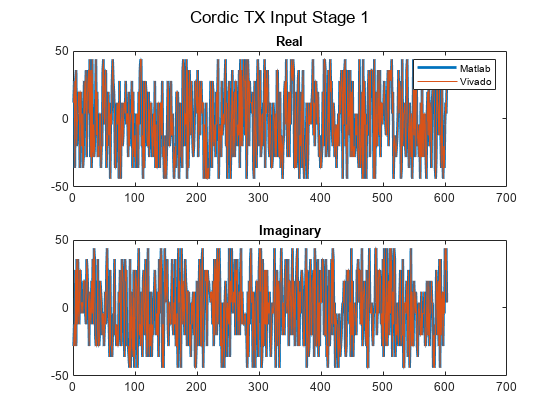

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Serial to Parallel
ofdm_signal_par = reshape(ofdm_signal_rx,[nfft+cp_len ofdm_symbols]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CFO Correction
cp_rm = ofdm_signal_par;
cp_rm(1:cp_len,:) = [];
ofdm_cfo_signal_par_eq = [];
cfo_est = 0;
for i = 1:ofdm_symbols
    cp_cfo_begin = ofdm_signal_par(1:cp_len,i);             % Obtain cyclic prefix at beginning of symbol
    cp_cfo_end = (ofdm_signal_par(nfft+1:end,i));       % Obtain cyclic prefix at end of symbol
    %cp_cfo_est = filter(cp_cfo_end,1,cp_cfo_begin);             % Correlate 
    tmp = cp_cfo_end.*conj(cp_cfo_begin);
    mult_val = complex(real(cp_cfo_end.*conj(cp_cfo_begin)),imag(cp_cfo_end.*conj(cp_cfo_begin)));
    sum_val = sum(mult_val);
    tan_val = atan2(imag(sum_val),real(sum_val));
    normalized_cfo_est = 1*tan_val;
    %normalized_cfo_est = 1/2/pi*angle(sum_val);
    %cfo_est = cfo_est + normalized_cfo_est * scs;
    cfo_est = normalized_cfo_est * scs;
    %ofdm_cfo_signal_par_eq(:,i) = cp_rm(:,i).*exp(1i*cfo_est*t(1:nfft))';
    ofdm_cfo_signal_par_eq(:,i) = cp_rm(:,i).*(cos(cfo_est*t(1:nfft))+1i*sin(cfo_est*t(1:nfft)))';
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FFT
fft_out_cfo = fft(ofdm_cfo_signal_par_eq,nfft);
fft_out_cfo = round(1e2*fft_out_cfo);

file = fopen('../../../HW/modules/sim/zf_equalizer/fft_out.txt','wt');
fft_out_cfo_scaled = reshape(fft_out_cfo,[1 nfft*ofdm_symbols]);
for i = 1:length(fft_out_cfo_scaled)
    if i == length(fft_out_cfo_scaled)
        fprintf(file,"%d, ",int16(real(fft_out_cfo_scaled(i))));
        fprintf(file,"%d",int16(imag(fft_out_cfo_scaled(i))));
    else
        fprintf(file,"%d, ",int16(real(fft_out_cfo_scaled(i))));
        fprintf(file,"%d\n",int16(imag(fft_out_cfo_scaled(i))));
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Obtain Pilots
P_RX = fft_out_cfo(pilot_index,:);
num = conj(P_RX); denom = conj(P); 
num_abs = abs(num); num_ang = angle(num); denom_abs = abs(denom); denom_ang = angle(denom);
H_ang = num_ang - denom_ang;
H_abs = num_abs ./ denom_abs;
H = H_abs .* exp(1i*H_ang);
H = num ./ denom;
H_ang1 = H_ang;
H_abs1 = H_abs;

% tmp_1 = abs(num);
% tmp_2 = abs(denom);
% tmp_11 = angle(num);
% tmp_22 = angle(denom);
% H2 = complex(tmp_1./tmp_2,tmp_22-tmp_11);
% 
% H_p = reshape(H,[1 ofdm_symbols*length(pilot_index)]);
% H2_p = reshape(H2,[1 ofdm_symbols*length(pilot_index)]);
% plot_length = 1:50;
% figure(),subplot(2,1,1),plot(abs(H_p(plot_length)),LineWidth=2),hold on,plot(abs(H2_p(plot_length))),title('ABS')
% subplot(2,1,2),plot(angle(H_p(plot_length)),LineWidth=2),hold on,plot(angle(H2_p(plot_length))),title('Angle')

file = fopen('../../../HW/modules/sim/zf_equalizer/cordic_tx_in.txt','r');
cordic_tx_in_vivado = [];
cordic_tx_in_mat = reshape(conj(P),[1 ofdm_symbols*pilot_carriers]);
for i = 1:length(cordic_tx_in_mat)
    tmp = fscanf(file,"%d");
    tmp2 = fscanf(file,",%d");
    tmp_out = complex(tmp,tmp2);
    cordic_tx_in_vivado = [cordic_tx_in_vivado tmp_out];
end
figure(),subplot(2,1,1),plot(real(cordic_tx_in_mat(plot_length)),LineWidth=2),hold on
plot(real(cordic_tx_in_vivado(plot_length))),legend('Matlab','Vivado'),title('Real'),subplot(2,1,2)
plot(imag(cordic_tx_in_mat(plot_length)),LineWidth=2),hold on
plot(-imag(cordic_tx_in_vivado(plot_length))),title('Imaginary'),sgtitle('Cordic TX Input Stage 1')

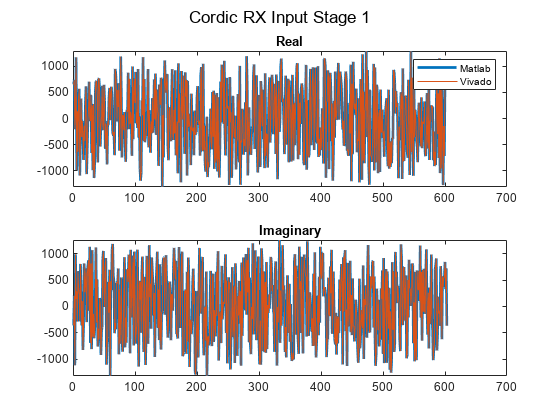

file = fopen('../../../HW/modules/sim/zf_equalizer/cordic_rx_in.txt','r');
cordic_rx_in_vivado = [];
cordic_rx_in_mat = reshape(conj(P_RX),[1 ofdm_symbols*pilot_carriers]);
for i = 1:length(cordic_rx_in_mat)
    tmp = fscanf(file,"%d");
    tmp2 = fscanf(file,",%d");
    tmp_out = complex(tmp,tmp2);
    cordic_rx_in_vivado = [cordic_rx_in_vivado tmp_out];
end
figure(),subplot(2,1,1),plot(real(cordic_rx_in_mat(plot_length)),LineWidth=2)
hold on,plot(real(cordic_rx_in_vivado(plot_length))),legend('Matlab','Vivado')
title('Real'),subplot(2,1,2),plot(imag(cordic_rx_in_mat(plot_length)),LineWidth=2),hold on
plot(-imag(cordic_rx_in_vivado(plot_length))),title('Imaginary'),sgtitle('Cordic RX Input Stage 1')

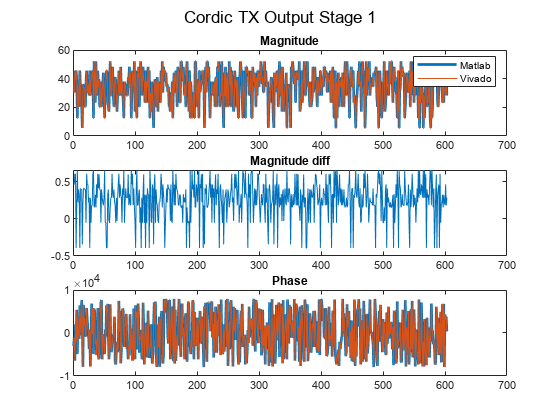

file = fopen('../../../HW/modules/sim/zf_equalizer/cordic_tx_out.txt','r');
cordic_tx_out_vivado_abs = [];
cordic_tx_out_vivado_angle = [];
cordic_tx_out_mat = reshape(conj(P),[1 ofdm_symbols*pilot_carriers]);
for i = 1:length(cordic_tx_out_mat)
    tmp = fscanf(file,"%d");
    tmp2 = fscanf(file,",%d");
    cordic_tx_out_vivado_abs = [cordic_tx_out_vivado_abs tmp];
    cordic_tx_out_vivado_angle = [cordic_tx_out_vivado_angle tmp2];
end
figure(),subplot(3,1,1),plot(abs(cordic_tx_out_mat(plot_length)),LineWidth=2),hold on
plot(cordic_tx_out_vivado_abs(plot_length)),legend('Matlab','Vivado'),title('Magnitude'),subplot(3,1,2)
plot(abs(cordic_tx_out_mat(plot_length))-cordic_tx_out_vivado_abs(plot_length)),title('Magnitude diff')
subplot(3,1,3),plot(scale*angle(cordic_tx_in_mat(plot_length)),LineWidth=2),hold on
plot(cordic_tx_out_vivado_angle(plot_length)),title('Phase'),sgtitle('Cordic TX Output Stage 1')

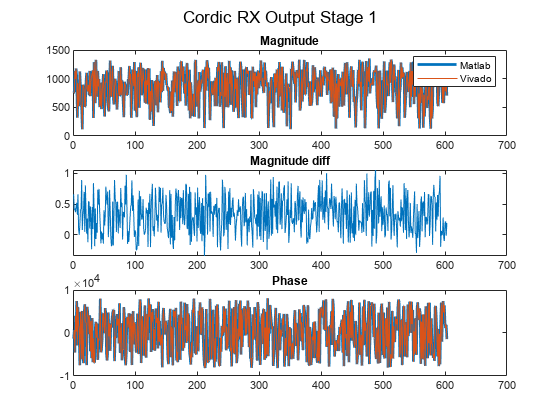

file = fopen('../../../HW/modules/sim/zf_equalizer/cordic_rx_out.txt','r');
cordic_rx_out_vivado_abs = [];
cordic_rx_out_vivado_angle = [];
cordic_rx_out_mat = reshape(conj(P_RX),[1 ofdm_symbols*pilot_carriers]);
for i = 1:length(cordic_rx_out_mat)
    tmp = fscanf(file,"%d");
    tmp2 = fscanf(file,",%d");
    cordic_rx_out_vivado_abs = [cordic_rx_out_vivado_abs tmp];
    cordic_rx_out_vivado_angle = [cordic_rx_out_vivado_angle tmp2];
end
abs_diff = abs(cordic_rx_out_mat(plot_length))-cordic_rx_out_vivado_abs(plot_length);
figure(),subplot(3,1,1),plot(abs(cordic_rx_out_mat(plot_length)),LineWidth=2),hold on
plot(cordic_rx_out_vivado_abs(plot_length)),legend('Matlab','Vivado'),title('Magnitude'),subplot(3,1,2),
plot(abs_diff),title('Magnitude diff')
subplot(3,1,3),plot(scale*angle(cordic_rx_in_mat(plot_length)),LineWidth=2),hold on
plot(cordic_rx_out_vivado_angle(plot_length)),title('Phase'),sgtitle('Cordic RX Output Stage 1')

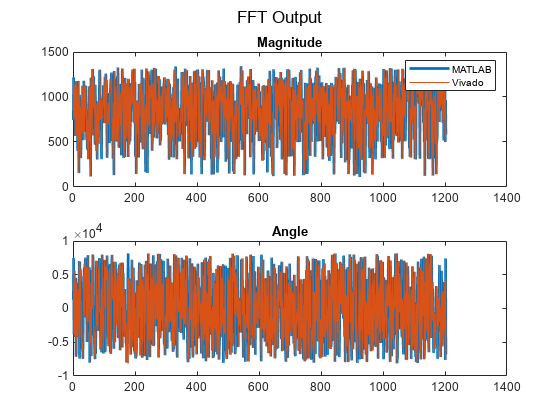

file = fopen('../../../HW/modules/sim/zf_equalizer/polar_data.txt','r');
mat_data = fft_out_cfo;
mat_data(zp_index,:) = [];
mat_data = reshape(mat_data,[1 (data_carriers + pilot_carriers)*ofdm_symbols]);
vivado_ang = []; vivado_abs = [];
for i = 1:length(mat_data)
    tmp = fscanf(file,"%d");
    vivado_abs = [vivado_abs tmp];
    tmp = fscanf(file,",%d");
    vivado_ang = [vivado_ang tmp];
end

figure(),subplot(2,1,1),plot(abs(mat_data(plot_length_data)),LineWidth=2),hold on,plot(vivado_abs(plot_length_data)),title('Magnitude'),legend('MATLAB','Vivado')
subplot(2,1,2),plot(scale*angle(mat_data(plot_length_data)),LineWidth=2),hold on,plot(vivado_ang(plot_length_data)),title('Angle'),sgtitle('FFT Output')

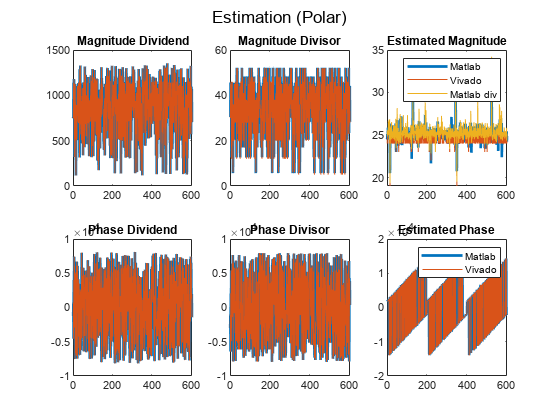


file = fopen('../../../HW/modules/sim/zf_equalizer/div_abs_in.txt','r');
file2 = fopen('../../../HW/modules/sim/zf_equalizer/div_ang_in.txt','r');
vivado_abs_denom = []; vivado_abs_num = []; vivado_ang_denom = []; vivado_ang_num = [];
for i = 1:length(reference_pilot_scaled)
    tmp = fscanf(file,"%d");
    vivado_abs_denom = [vivado_abs_denom tmp];
    tmp = fscanf(file,",%d");
    vivado_abs_num = [vivado_abs_num tmp];
    tmp = fscanf(file2,"%d");
    vivado_ang_denom = [vivado_ang_denom tmp];
    tmp = fscanf(file2,",%d");
    vivado_ang_num = [vivado_ang_num tmp];    
end
file = fopen('../../../HW/modules/sim/zf_equalizer/div_1_full.txt','r');
vivado_abs_res = [];
vivado_ang_res = [];
for i = 1:length(reference_pilot_scaled)
    tmp = fscanf(file,"%d");
    vivado_abs_res = [vivado_abs_res tmp];
    tmp = fscanf(file,",%d");
    vivado_ang_res = [vivado_ang_res tmp];
end

denom_abs = reshape(denom_abs, [1 ofdm_symbols*pilot_carriers]);
denom_ang = reshape(denom_ang, [1 ofdm_symbols*pilot_carriers]);
num_abs = reshape(num_abs, [1 ofdm_symbols*pilot_carriers]);
num_ang = reshape(num_ang, [1 ofdm_symbols*pilot_carriers]);
H_abs = reshape(H_abs, [1 ofdm_symbols*pilot_carriers]);
H_ang = reshape(H_ang, [1 ofdm_symbols*pilot_carriers]);
H_viv_mat_abs = vivado_abs_num ./ vivado_abs_denom;
figure(),subplot(2,3,2),plot(denom_abs(plot_length),LineWidth=2),hold on,plot(vivado_abs_denom(plot_length)),title('Magnitude Divisor')
subplot(2,3,5),plot(scale*denom_ang(plot_length),LineWidth=2),hold on,plot(vivado_ang_denom(plot_length)),title('Phase Divisor')
subplot(2,3,1),plot(num_abs(plot_length),LineWidth=2),hold on,plot(vivado_abs_num(plot_length)),title('Magnitude Dividend')
subplot(2,3,4),plot(scale*num_ang(plot_length),LineWidth=2),hold on,plot(vivado_ang_num(plot_length)),title('Phase Dividend')
subplot(2,3,3),plot(H_abs(plot_length),LineWidth=2),hold on,plot(vivado_abs_res(plot_length)),plot(H_viv_mat_abs(plot_length)),legend('Matlab','Vivado','Matlab div'),title('Estimated Magnitude')
subplot(2,3,6),plot(scale*H_ang(plot_length),LineWidth=2),hold on,plot(vivado_ang_res(plot_length)),legend('Matlab','Vivado'),title('Estimated Phase')
sgtitle('Estimation (Polar)')

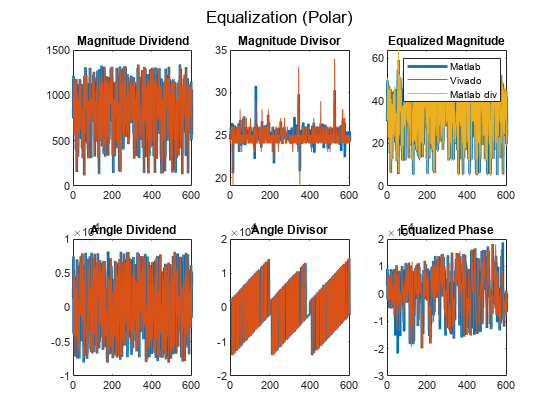

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Normal ZF equalization
H_ZF_interp = interp1(pilot_index,H,1:nfft,'nearest');
Z_EQ_ZF = fft_out_cfo ./ conj(H_ZF_interp);

H_ZF_interp_abs = interp1(pilot_index,H_abs1,1:nfft,'nearest');
H_ZF_interp_ang = interp1(pilot_index,H_ang1,1:nfft,'nearest');

Z_EQ_ZF_abs = abs(fft_out_cfo) ./ H_ZF_interp_abs;
Z_EQ_ZF_abs([zp_index],:) = [];
Z_EQ_ZF_ang = angle(fft_out_cfo) + H_ZF_interp_ang;
Z_EQ_ZF_ang([zp_index],:) = [];

% Vivado channel estimation
H_vivado = vivado_abs_res .* exp(1i*vivado_ang_res / scale);
%I H_vivado = H_abs .* exp(-1i*vivado_ang_res / scale);
H_vivado = reshape(H_vivado,[pilot_carriers ofdm_symbols]);
H_ZF_interp_vivado = interp1(pilot_index,H_vivado,1:nfft,'nearest');
Z_EQ_ZF_vivado = fft_out_cfo ./ conj(H_ZF_interp_vivado);

Z_EQ_ZF_ZP = Z_EQ_ZF;
Z_EQ_ZF_ZP([zp_index],:) = [];
Z_EQ_ZF_ZP_P = Z_EQ_ZF;
Z_EQ_ZF_ZP_P([zp_index,pilot_index],:) = [];
file = fopen('../../../HW/modules/sim/zf_equalizer/eq_din_1.txt','r');
R_abs_vivado = []; R_ang_vivado = [];
fft_out_cfo_scaled_zp = fft_out_cfo;
fft_out_cfo_scaled_zp([zp_index],:) = [];
fft_out_cfo_scaled_zp = reshape(fft_out_cfo_scaled_zp,[1 ofdm_symbols*(data_carriers + pilot_carriers)]);
for i = 1:length(fft_out_cfo_scaled_zp)
    tmp = fscanf(file,"%d");
    R_abs_vivado = [R_abs_vivado tmp];
    tmp = fscanf(file,",%d");
    R_ang_vivado = [R_ang_vivado tmp];
end
file = fopen('../../../HW/modules/sim/zf_equalizer/eq_est_1.txt');
H_abs_vivado = [];
H_phase_vivado = [];
for i = 1:length(reference_pilot_scaled)
    tmp = fscanf(file,"%d");
    H_abs_vivado = [H_abs_vivado tmp];
    tmp = fscanf(file,",%d");
    H_phase_vivado = [H_phase_vivado tmp];
end
file = fopen('../../../HW/modules/sim/zf_equalizer/eq_1.txt','r');
Z_EQ_abs_vivado = [];
Z_EQ_ang_vivado = [];
Z_EQ_ZF_ZP = reshape(Z_EQ_ZF_ZP, [1 (pilot_carriers+data_carriers)*ofdm_symbols]);
for i = 1:length(Z_EQ_ZF_ZP)
    tmp = fscanf(file,"%d");
    Z_EQ_abs_vivado = [Z_EQ_abs_vivado tmp];
    tmp = fscanf(file,",%d");
    Z_EQ_ang_vivado = [Z_EQ_ang_vivado tmp];
end
H_vivado = complex(H_abs_vivado,H_phase_vivado);
H_vivado = reshape(H_vivado,[pilot_carriers ofdm_symbols]);
H_tmp = reshape(H,[1 ofdm_symbols*pilot_carriers]);
mat_H_abs_vivado = reshape(H_abs_vivado,[pilot_carriers ofdm_symbols]);
mat_H_ang_vivado = reshape(H_phase_vivado,[pilot_carriers ofdm_symbols]);
mat_H_vivado =  mat_H_abs_vivado .* exp(-1i*mat_H_ang_vivado);
mat_H_abs_vivado1 = interp1(pilot_index,mat_H_vivado,1:nfft,'nearest');
mat_H_abs_vivado1(zp_index,:) = [];
Z_EQ_ZF_ang_re = reshape(Z_EQ_ZF_ang,[1 ofdm_symbols*(pilot_carriers+data_carriers)]);
Z_EQ_ZF_abs_re = reshape(Z_EQ_ZF_abs,[1 ofdm_symbols*(pilot_carriers+data_carriers)]);
mat_H_abs_vivado1 = reshape(mat_H_abs_vivado1,[1 ofdm_symbols*(pilot_carriers+data_carriers)]);
mat_div_mag = R_abs_vivado./mat_H_abs_vivado1;
figure(),subplot(2,3,1),plot(abs(fft_out_cfo_scaled_zp(plot_length)),'LineWidth',2),hold on,plot(R_abs_vivado(plot_length)),title('Magnitude Dividend')
subplot(2,3,4),plot(scale*angle(fft_out_cfo_scaled_zp(plot_length)),'LineWidth',2),hold on,plot(R_ang_vivado(plot_length)),title('Angle Dividend')
subplot(2,3,2),plot(H_abs(plot_length),'LineWidth',2),hold on,plot(H_abs_vivado(plot_length)),title('Magnitude Divisor')
subplot(2,3,5),plot(scale*H_ang(plot_length),'LineWidth',2),hold on,plot(H_phase_vivado(plot_length)),title('Angle Divisor')
subplot(2,3,3),plot(abs(Z_EQ_ZF_ZP(plot_length)),'LineWidth',2),hold on,plot(Z_EQ_abs_vivado(plot_length))
plot(abs(mat_div_mag(plot_length))),title('Equalized Magnitude'),legend('Matlab','Vivado','Matlab div')
subplot(2,3,6),plot(scale*Z_EQ_ZF_ang_re(plot_length),'LineWidth',2),hold on,plot(Z_EQ_ang_vivado(plot_length))
mat_div_ang = R_ang_vivado(plot_length)/scale - H_phase_vivado(plot_length)/scale;
%plot(mat_div_ang(plot_length)),legend('Matlab','Vivado','Matlab div'),
title('Equalized Phase')
sgtitle('Equalization (Polar)')

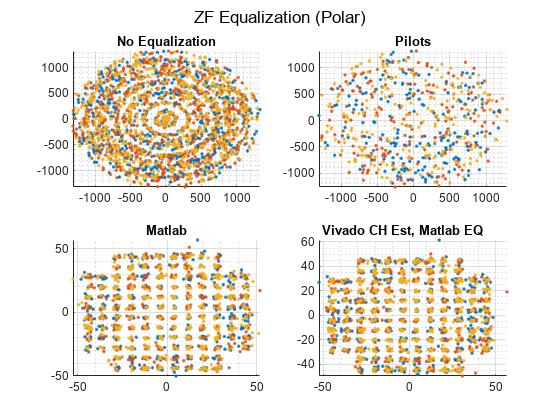

% figure(),subplot(2,3,1),plot(abs(fft_out_cfo_scaled_zp(plot_length)),'LineWidth',2),hold on,plot(R_abs_vivado(plot_length)),title('Magnitude Dividend')
% subplot(2,3,4),plot(angle(fft_out_cfo_scaled_zp(plot_length)),'LineWidth',2),hold on,plot(R_ang_vivado(plot_length)/scale),title('Angle Dividend')
% subplot(2,3,2),plot(H_abs(plot_length),'LineWidth',2),hold on,plot(H_abs_vivado(plot_length)),title('Magnitude Divisor')
% subplot(2,3,5),plot(H_ang(plot_length),'LineWidth',2),hold on,plot(H_phase_vivado(plot_length)/scale),title('Angle Divisor')
% subplot(2,3,3),plot(abs(Z_EQ_ZF_ZP(plot_length)),'LineWidth',2),hold on,plot(Z_EQ_abs_vivado(plot_length))
% plot(abs(mat_div_mag(plot_length))),title('Equalized Magnitude'),legend('Matlab','Vivado','Matlab div')
% subplot(2,3,6),plot(angle(Z_EQ_ZF_ZP(plot_length)),'LineWidth',2),hold on,plot(Z_EQ_ang_vivado(plot_length)/scale),
% mat_div_ang = R_ang_vivado(plot_length)/scale - H_phase_vivado(plot_length)/scale;
% %plot(mat_div_ang(plot_length)),legend('Matlab','Vivado','Matlab div'),
% title('Equalized Phase')
% sgtitle('Equalization Scaled')
%figure(),plot(angle(Z_EQ_ZF_ZP(plot_length)),'LineWidth',2),hold on,plot(Z_EQ_ang_vivado(plot_length)/scale),
%plot(mat_div_ang(plot_length)),legend('Matlab','Vivado','Matlab div'),title('Normalized Equalized Phase')

Z_EQ_ZF([pilot_index,zp_index],:) = [];
figure(),subplot(2,2,1),scatter(real(fft_out_cfo),imag(fft_out_cfo),'.','LineWidth',2),grid on,grid minor,title('No Equalization')
subplot(2,2,2),scatter(real(P_RX),imag(P_RX),'.','LineWidth',2),grid on,grid minor,title('Pilots')
subplot(2,2,3),scatter(real(Z_EQ_ZF),imag(Z_EQ_ZF),'.','LineWidth',2),grid on,grid minor,title('Matlab')
subplot(2,2,4),scatter(real(Z_EQ_ZF_vivado),imag(Z_EQ_ZF_vivado),'.','LineWidth',2),grid on,grid minor,title('Vivado CH Est, Matlab EQ     ')
sgtitle('ZF Equalization (Polar)')

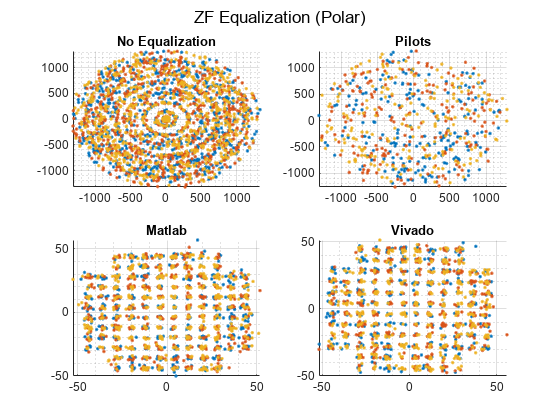

Z_EQ_Vivado = Z_EQ_abs_vivado .* exp(-1j*Z_EQ_ang_vivado / scale);
scale2 = 2^16/250000000;
scale2 = 1;
dds = cos(scale2*1*Z_EQ_ang_vivado/scale) + 1j*sin(scale2*1*Z_EQ_ang_vivado/scale);
Z_EQ_Vivado = Z_EQ_abs_vivado .* dds;
%Z_EQ_Vivado = Z_EQ_abs_vivado .* exp(-1j*angle(Z_EQ_ZF_ZP));
%Z_EQ_Vivado = Z_EQ_ZF_abs_re .* exp(-1j*Z_EQ_ZF_ang_re);
%Z_EQ_Vivado = Z_EQ_ZF_abs_re .* exp(-1j*angle(Z_EQ_ZF_ZP));
Z_EQ_Vivado1 = reshape(Z_EQ_Vivado,[ofdm_symbols pilot_carriers+data_carriers]);
Z_EQ_Vivado2 = [zeros(ofdm_symbols,111) Z_EQ_Vivado1 zeros(ofdm_symbols,112)];
Z_EQ_Vivado2 = Z_EQ_Vivado2';
Z_EQ_Vivado2([zp_index,pilot_index],:) = [];
figure(),subplot(2,2,1),scatter(real(fft_out_cfo),imag(fft_out_cfo),'.','LineWidth',2),grid on,grid minor,title('No Equalization')
subplot(2,2,2),scatter(real(P_RX),imag(P_RX),'.','LineWidth',2),grid on,grid minor,title('Pilots')
subplot(2,2,3),scatter(real(Z_EQ_ZF),imag(Z_EQ_ZF),'.','LineWidth',2),grid on,grid minor,title('Matlab')
subplot(2,2,4),scatter(real(Z_EQ_Vivado2),imag(Z_EQ_Vivado2),'.','LineWidth',2),grid on,grid minor,title('Vivado')
sgtitle('ZF Equalization (Polar)')

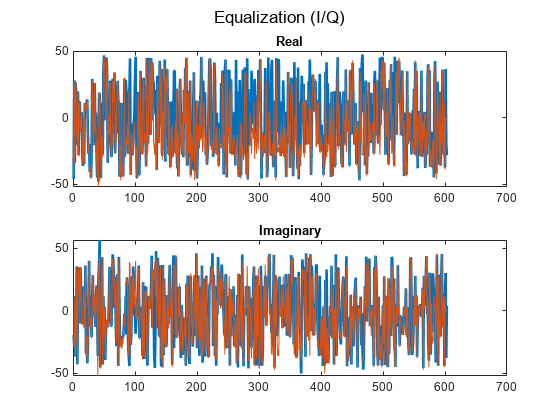

% dds1    = dds_compiler_v6_0_bitacc()
%file = fopen('../../../HW/modules/sim/zf_equalizer/dds.txt','r');
% dds_out = run(dds1,length(Z_EQ_ang_vivado));
% figure(),hold on,grid on,plot(dds_out(:,:,1)/max(abs(dds_out(:,:,1))),'g')
% plot(dds_out(:,:,2)/max(abs(dds_out(:,:,2))),'r'),plot(dds_out(:,:,3)/max(abs(dds_out(:,:,3))),'b')
% legend('Phase Out','Sin Out','Cos Out'),title('Xilinx DDS MATLAB Model')
% destroy(dds1);
% dds1 = dds_compiler_v6_0_bitacc('DDS_Clock_Rate',250,'Phase_Increment',3)
% %dds_out = run(dds1,length(Z_EQ_ang_vivado),double(Z_EQ_ang_vivado/scale/2/pi));
% destroy(dds1);
% dds_i = [];
% dds_q = [];
% for i = 1:length(dds)
%     tmp = fscanf(file,"%d");
%     dds_i = [dds_i tmp];
%     tmp = fscanf(file,",%d");
%     dds_q = [dds_q tmp];
% end
%figure(),subplot(2,1,1),plot(dds_out)
% figure(),subplot(2,1,1),plot(13*scale*real(dds(plot_length)),'LineWidth',2),hold on,plot(dds_i(plot_length)),title('Real')
% subplot(2,1,2),plot(13*scale*imag(dds(plot_length)),'LineWidth',2),hold on,plot(dds_q(plot_length)),title('Imaginary'),sgtitle('DDS')
file = fopen('../../../HW/modules/sim/zf_equalizer/eq_out.txt','r');
Z_EQ_i_vivado = [];
Z_EQ_q_vivado = [];
Z_EQ_ZF_ZP_P = reshape(Z_EQ_ZF_ZP_P,[1 ofdm_symbols*(data_carriers)]);
for i = 1:length(Z_EQ_ZF_ZP_P)
    tmp = fscanf(file,"%d");
    Z_EQ_i_vivado = [Z_EQ_i_vivado tmp];
    tmp = fscanf(file,",%d");
    Z_EQ_q_vivado = [Z_EQ_q_vivado tmp];
end
Z_EQ_i_vivado(1:3) = [];
Z_EQ_q_vivado(1:3) = [];
Z_EQ_i_vivado = [Z_EQ_i_vivado 0 0 0];
Z_EQ_q_vivado = [Z_EQ_q_vivado 0 0 0];
figure(),subplot(2,1,1),plot(real(Z_EQ_ZF_ZP_P(plot_length)),'LineWidth',2),hold on,plot(Z_EQ_i_vivado(plot_length)),title('Real')
subplot(2,1,2),plot(imag(Z_EQ_ZF_ZP_P(plot_length)),'LineWidth',2),hold on,plot(Z_EQ_q_vivado(plot_length)),title('Imaginary')
sgtitle('Equalization (I/Q)')

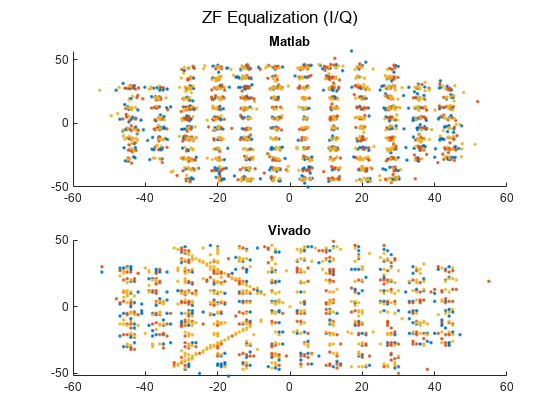

EQ_Vivado = complex(Z_EQ_i_vivado,Z_EQ_q_vivado);
EQ_Vivado = reshape(EQ_Vivado,[data_carriers ofdm_symbols]);
%EQ_Vivado([1:112 end-112:end],:) = [];
figure(),subplot(2,1,1),scatter(real(Z_EQ_ZF),imag(Z_EQ_ZF),'.','LineWidth',2),title('Matlab')
subplot(2,1,2),scatter(real(EQ_Vivado),imag(EQ_Vivado),'.','LineWidth',2),title('Vivado')
sgtitle("ZF Equalization (I/Q)")

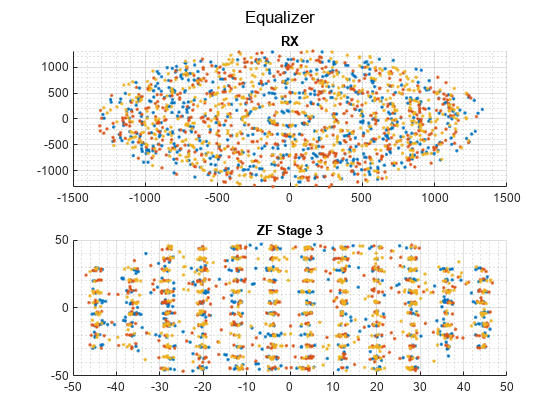

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Equalization Stage 1
H_mean = mean(H);
H_mean = mean(H_vivado);
Z_EQ1 = fft_out_cfo ./ conj(H_mean);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Estimation Stage 2
Z_EQ1_pilots = Z_EQ1(pilot_index,:);
H2 = conj(Z_EQ1_pilots) ./ conj(P);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilot Window Averaging
H_ZF_save = zeros(pilot_carriers,ofdm_symbols);
ZEQ2 = [];
for i = 1:ofdm_symbols
    for k = 1:pilot_carriers
        index = ((rep)*(k-1)+1:(rep)*k) + zp_index(ceil(end/2)-1);
        ind_lo = k-floor(freq_avg/2);
        ind_hi = k+floor(freq_avg/2);
        if ind_lo < 1
            ind_lo = 1;
        end
        if ind_hi > pilot_carriers
            ind_hi = pilot_carriers;
        end
        i_lo = i-floor(time_avg/2);
        i_hi = i+floor(time_avg/2);
        if i_lo < 1
            i_lo = 1;
        end
        if i_hi > ofdm_symbols
            i_hi = ofdm_symbols;
        end
        H_tmp = mean(mean(H2(ind_lo:ind_hi,i_lo:i_hi)));
        H_ZF_save(k,i) = conj(H_tmp);
        H_est_avg(index,i) = ones(1,length(index))*H_tmp;
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Interpolate Channel Estimates
H2_interp = interp1(pilot_index,H_ZF_save,1:nfft,'spline');
Z_EQ2 = Z_EQ1 ./ H2_interp;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Estimation Stage 3
Z_EQ2_pilots = Z_EQ2(pilot_index,:);
H3 = conj(Z_EQ2_pilots) ./ conj(P);
H3_P = mean(H3);
Z_EQ3 = Z_EQ2 ./ conj(H3_P);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Remove ZP and pilot index
Z_EQ3([pilot_index,zp_index],:) = [];
fft_out_cfo([pilot_index,zp_index],:) = [];

lim = sqrt(M) + 1.5;
y_lim = [-lim lim];
x_lim = y_lim;
figure(),subplot(2,1,1),scatter(real(fft_out_cfo),imag(fft_out_cfo),'.','LineWidth',2),grid on,grid minor,title('RX')
subplot(2,1,2),scatter(real(Z_EQ3),imag(Z_EQ3),'.','LineWidth',2),grid on,grid minor, title('ZF Stage 3')
sgtitle('Equalizer')

**Cleanup**

fclose('all');